# Procesat d'Imatges 1.2

## Exercici Nebulosa d'Orion

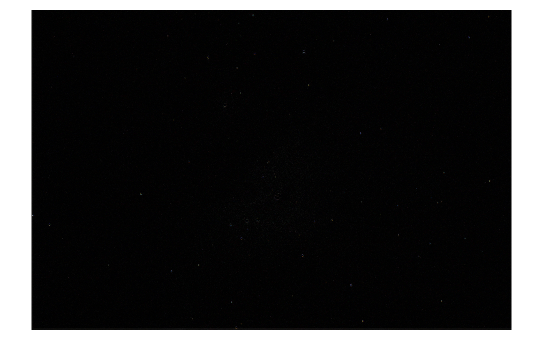

A = double(imread('_MG_7735.JPG'))/255;
B = double(imread('_MG_7737.JPG'))/255;
B = imtranslate(B, [20, -20]);
C = abs(A - B);
imshow(C);

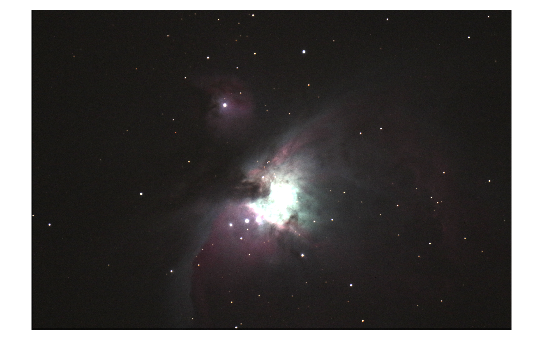

D = A + B;
imshow(D)

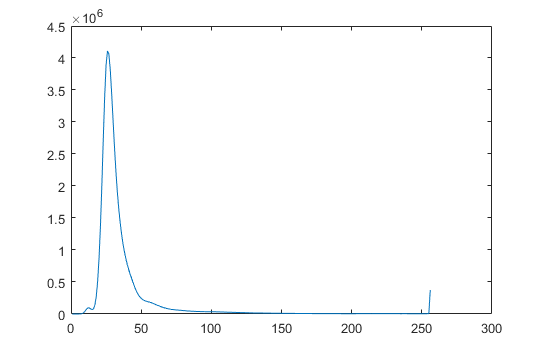

HD = imhist(D);
plot(HD);

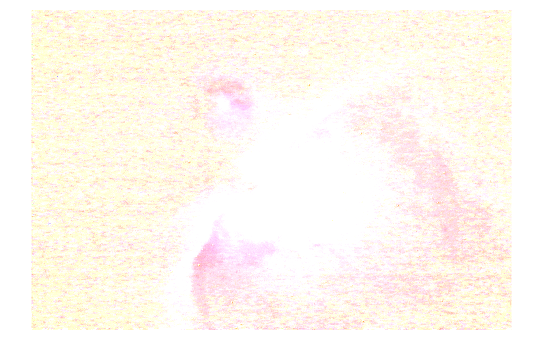

E = rgb2hsv(D);
%E(:,:,2) = E(:,:, 2)*1.4;
E(:,:,3) = pow2(E(:,:,3)-0.02);
J = hsv2rgb(E);
imshow(J);

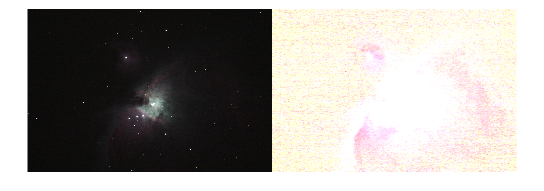

montage({A, J})

## Detectar diferències en un vídeo

v = VideoReader('atrium.mp4');

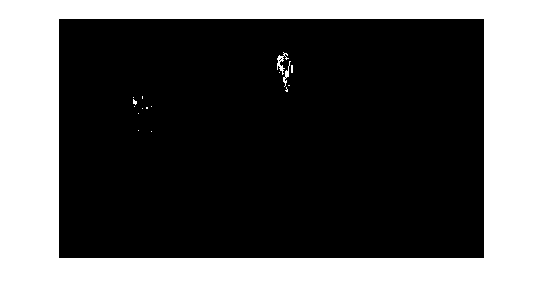

Background = double(rgb2gray(readFrame(v)));
while hasFrame(v)
    Actual = double(rgb2gray(readFrame(v)));
    Dif = abs(Actual-Background) > 40;
    imshow(Dif, []);
    drawnow
    Background = 0.9*Background + 0.1*Actual;
end